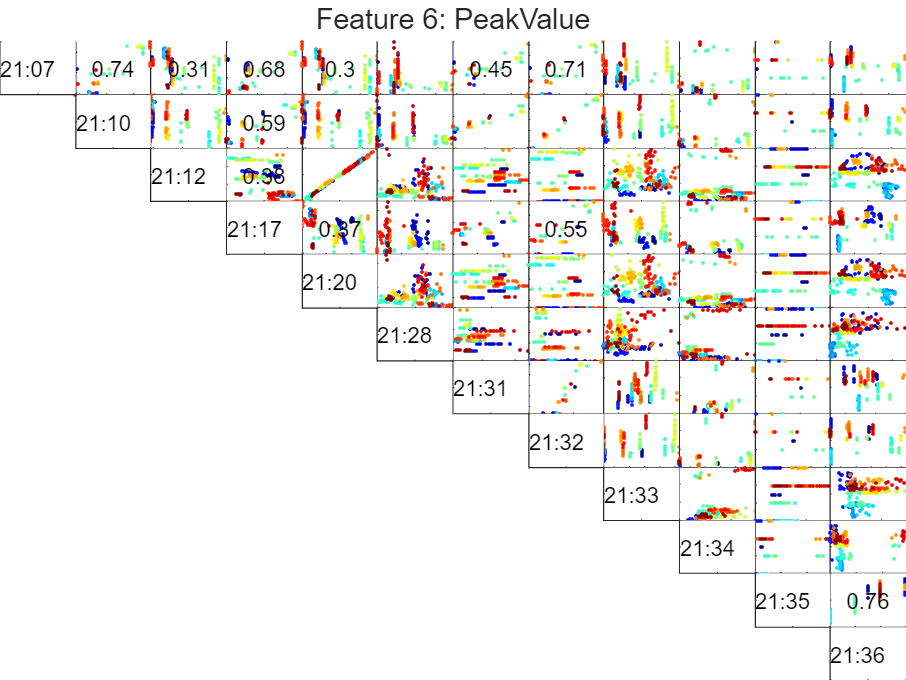

Features = DFD_FeatureTable_TimeDomain;
SignalNames = signalNames_Time;
FeatureNames = featureNames_Time;
lowerR2 = 0.3;
upperR2 = 0.8;
featureNum = 6; % Peak value
R2 = fnPlotSignalVsSignal(Features, lowerR2, upperR2, featureNum, FeatureNames, SignalNames, sensorNames);        

disp(num2str(R2, '%.2f  '));

0.00  0.74  0.31  0.68  0.30  0.03  0.45  0.71  0.01  0.00  0.00  0.02
0.00  0.00  0.18  0.59  0.18  0.00  0.82  0.99  0.11  0.06  0.00  0.00
0.00  0.00  0.00  0.38  0.99  0.00  0.01  0.17  0.00  0.00  0.15  0.05
0.00  0.00  0.00  0.00  0.37  0.00  0.30  0.55  0.00  0.02  0.09  0.02
0.00  0.00  0.00  0.00  0.00  0.00  0.01  0.17  0.00  0.00  0.15  0.05
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.04  0.04  0.22  0.26
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.82  0.13  0.11  0.02  0.01
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.13  0.07  0.00  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.21  0.03  0.04
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.01
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.76
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00


selectedSignal = 1; % row 1
selectedSignalArray = [selectedSignal]; % Array of correlated features
for i = 1:numOfSignals + 1 - selectedSignal
    if R2(i,selectedSignal) > lowerR2 && R2(i,selectedSignal) < upperR2
        selectedSignalArray = [selectedSignalArray i];
    end
end
for i = selectedSignal + 1:numOfSignals
    if R2(selectedSignal,i) > lowerR2 && R2(selectedSignal,i) < upperR2
        selectedSignalArray = [selectedSignalArray i];
    end
end
selectedSignalArray = sort(selectedSignalArray);
numOfSelectedSignals = size(selectedSignalArray, 2);
selectedSignalData = {numOfSelectedSignals};

for signalIndex = 1:numOfSelectedSignals
    selectedSignalData{signalIndex} = Features.(signalNames(signalIndex) + FeatureNames(featureNum));
end

disp(selectedSignalArray);

     1     2     3     4     5     7     8



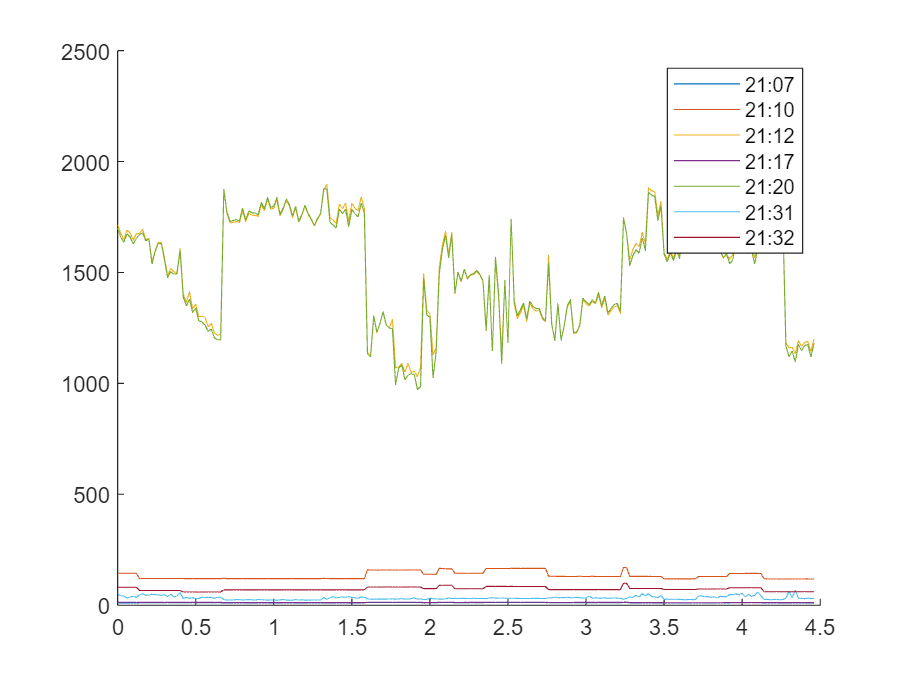

n = size(selectedSignalData{1}, 1);
t = ( 0 : 1/fs : (n / fs) - 1/fs)';
figure(); hold on
leg = {numOfSelectedSignals};
for i = 1:numOfSelectedSignals
    plot(t, selectedSignalData{i});
    txtTemp = char(sensorNames(selectedSignalArray(i)));
    leg{i} = char(txtTemp(1:5));
end
legend(leg);

X_signals = zeros(n, numOfSelectedSignals);
for i = 1:numOfSelectedSignals
    X_signals(:,i) = selectedSignalData{i}; 
end

% Model candidate 1
X_1 = X_signals(:,1);
X_2 = X_signals(:,2);
X_3 = X_signals(:,3);
X_4 = X_signals(:,4);
X_5 = X_signals(:,5);
X_6 = X_signals(:,6);

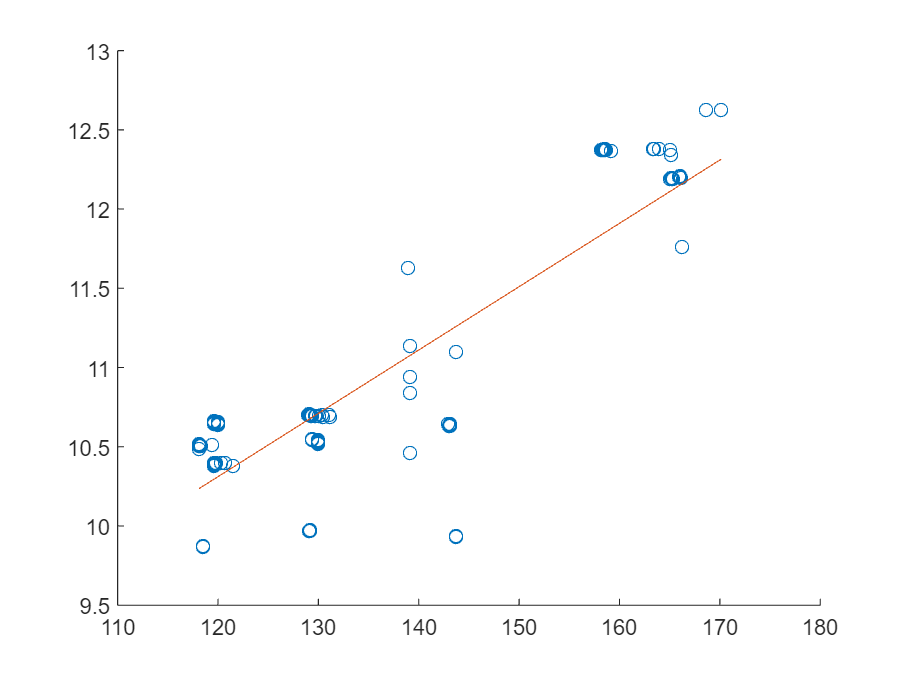

% Single variable Model candidate 1
X1 = X_2;
X = [ones(n,1) X1];
Y = X_1;
k = size(X, 2) - 1; % Number of parameters for model
beta = inv(X' * X) * (X' * Y);

Y_est = X * beta;
RSS = sum((Y_est - Y).^2);
RSS = var(Y_est - Y) / var(Y);

figure(); hold on;
scatter(X1, Y);
interval = max(X1) - min(X1);
x1fit = min(X1):interval:max(X1);
yfit = beta(1) + beta(2).*x1fit;
plot(x1fit, yfit);

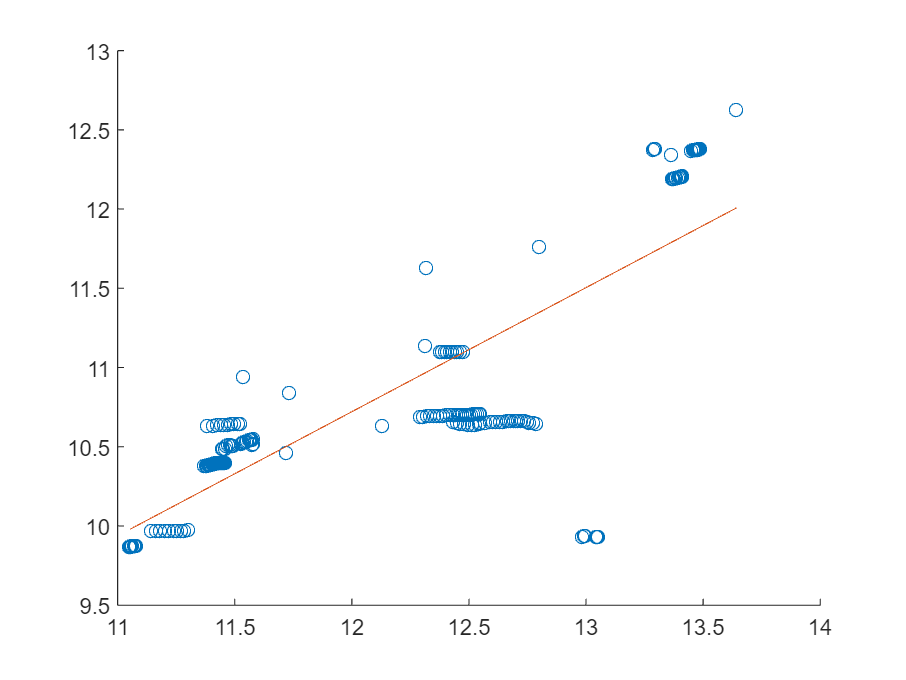

% Single variable Model candidate 2
X1 = X_4;
X = [ones(n,1) X1];
Y = X_1;
k = size(X, 2) - 1; % Number of parameters for model
beta = inv(X' * X) * (X' * Y);

Y_est = X * beta;
RSS = sum((Y_est - Y).^2);
RSS = var(Y_est - Y) / var(Y);

figure(); hold on;
scatter(X1, Y);
interval = max(X1) - min(X1);
x1fit = min(X1):interval:max(X1);
yfit = beta(1) + beta(2).*x1fit;
plot(x1fit, yfit);

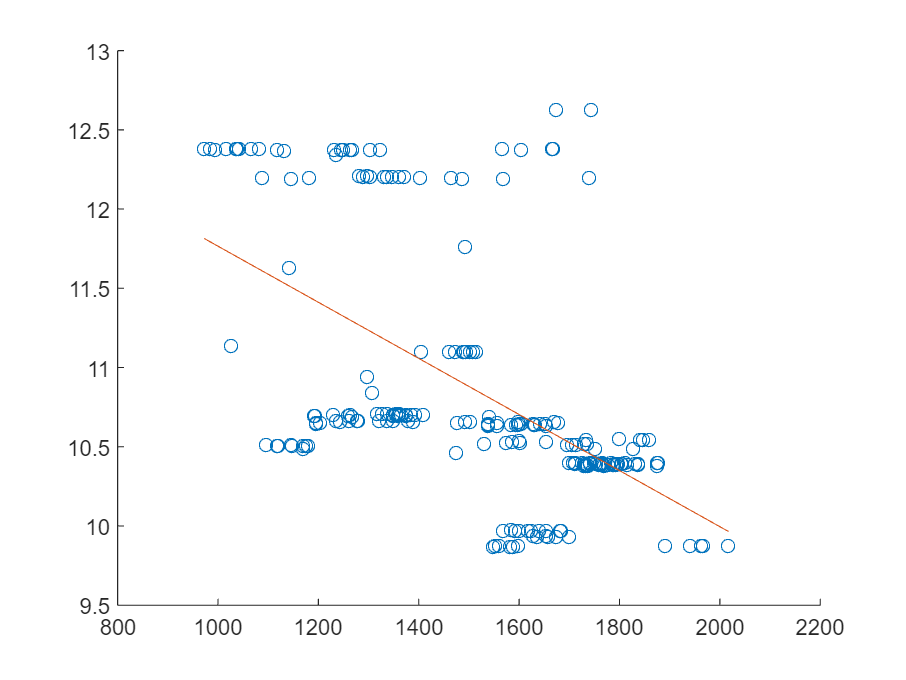

% Single variable Model candidate 2
X1 = X_5;
X = [ones(n,1) X1];
Y = X_1;
k = size(X, 2) - 1; % Number of parameters for model
beta = inv(X' * X) * (X' * Y);

Y_est = X * beta;
RSS = sum((Y_est - Y).^2);
RSS = var(Y_est - Y) / var(Y);

figure(); hold on;
scatter(X1, Y);
interval = max(X1) - min(X1);
x1fit = min(X1):interval:max(X1);
yfit = beta(1) + beta(2).*x1fit;
plot(x1fit, yfit);